
%Number of corners + boolean for answer
numOfParamaters = 3;

%How many choices the test taker has
numOfOptions = 4;

I1 = imread('original.png');
I2 = imread ('answers.png');
I3 = imread ('student.png');

% Blank, Answer Key, Student Answers
B = rot90(I1);
A = rot90(I2);
S = rot90(I3);


%Get red and green channels
RED = A(:,:,1);
GREEN = A(:,:,2);



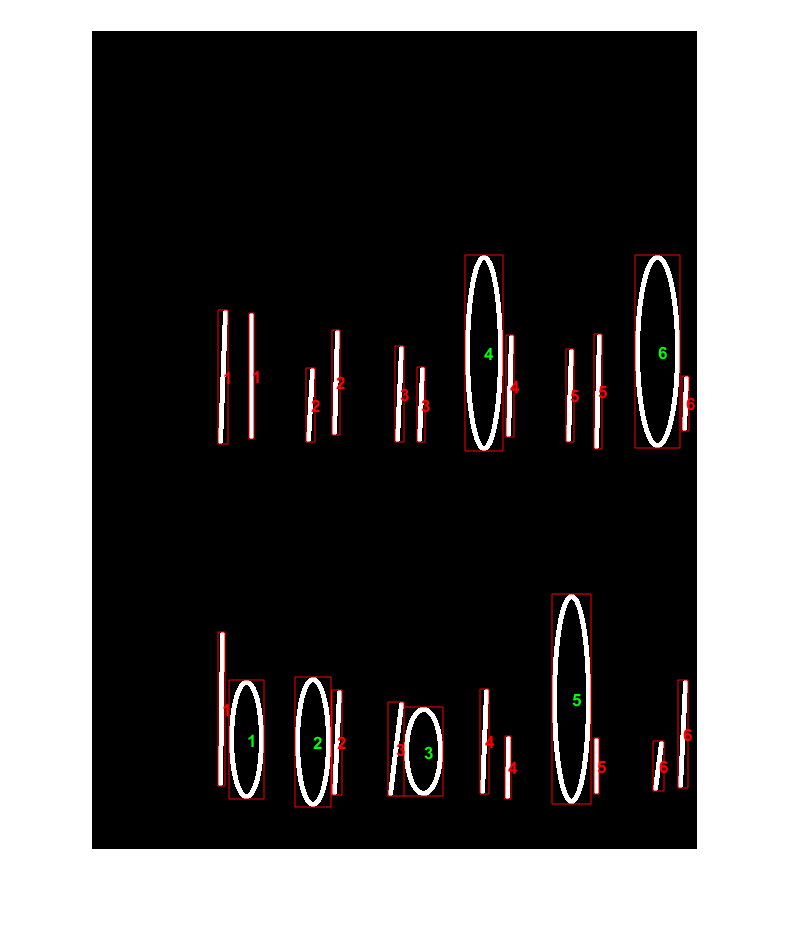

%Get only the red marks
I = im2bw(RED - GREEN,.5);
imshow(I);

% Get red blob regions
[L,numOfBlobs] = bwlabel(I);

%Print out the number of questions that we have detected
numOfQuestions= numOfBlobs/numOfOptions;
disp(strcat('Number of Questions detected' + num2str(numOfQuestions)));


%option1 = [1,2,3];
%option2 = [4,5,6];
%option3 = [7,8,9];
%option4 = [10,11,12];

%arrayOfOptions =cat(3, option1,option2,option3,option4);
%disp(arrayOfOptions(1,2,2));

%arrayOfQuestions = cat(numOfQuestions,arrayOfOptions,arrayOfOptions,arrayOfOptions,arrayOfOptions);

%disp(arrayOfQuestions(1,2,2));

props = regionprops(L, 'all');

%Initialize the question counter and the Question Number
count = 1;
questionNum = 1;

for i=1:numOfBlobs
    % Each region is part of a Question
    if(count > numOfOptions)
        count = 1;
        % Increment Question number every NUM_Q
        questionNum = questionNum +1;
    end
    
    % Get the bounding box for the option
    % Bounding box will be expanded for non-answers
    bb = props(i).BoundingBox;     
    
    % See if it is an answer and then assign a r or g
    % (note: this could also be true of false)
    isAnswer = 'r';  
    if(props(i).BoundingBox(3)>30)
        isAnswer = 'g';
    end
    
    % Options will have the coordinates of the box, and whether it is an answer
    tempOption = [bb(1) bb(2) bb(3) bb(4) isAnswer]
    
    % Add the option information to the question.
    tempArrayOfOptions = cat(1, arrayOfOptions,tempOption);
    
    % Draw Text and Bounding box
    rectangle('Position',bb,'EdgeColor','r');
    text(props(i).Centroid(1),props(i).Centroid(2),num2str(questionNum),'Color',isAnswer,...
       'FontSize',10,'FontWeight','bold');
    
    count = count +1;
    
   % if(props(i).BoundingBox(4)>30)
        
   
 end